# Group Assignment 06 Contagious Diseases Ebola Outbreak II

We continue with the ebola outbreak from lesson 2. Ten patients are admitted to a hospital. Assume that each patient has a chance of 0.5 of being infected. We define a random variable 𝑋𝑋 that is the total number of infected patients at day 0.

## Process 1:

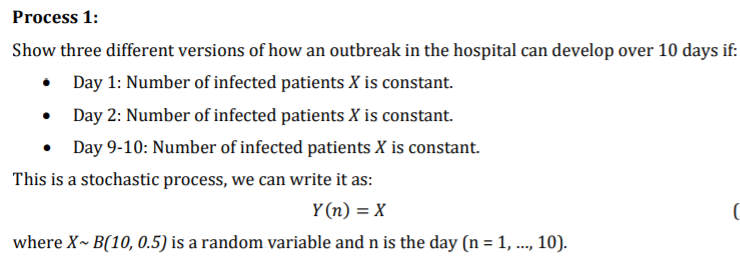

1. Make a Matlab function that generates realizations of the process Y(n).

nbr_days = 10;
infection_chance = 0.5;
X_day_one = 0;
nbr_patients = 10;
infected_realizations = binornd(nbr_days, infection_chance, 1, 3)

infected_realizations =      3     4     4


2. Plot three realizationer of the process.

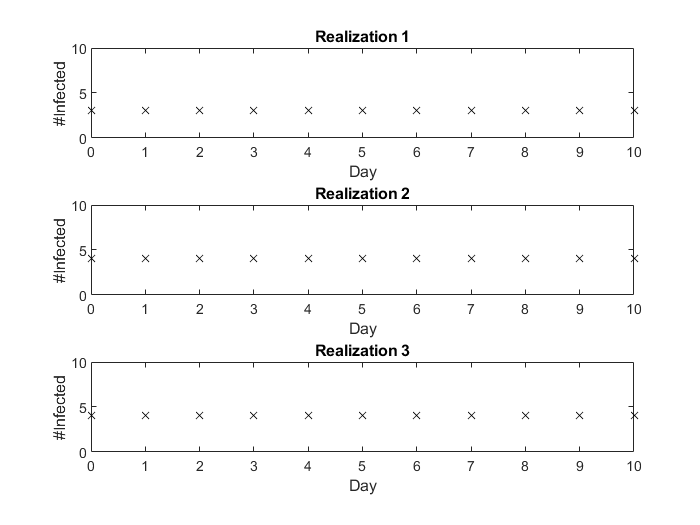

figure(1)
for i = 1 : 3
    ax = subplot(3,1,i);
    x = linspace(0,nbr_patients,11);
    plot(ax, x, infected_realizations(i), 'kx');
    axis([0,10,0,10]);
    title(ax,['Realization ',num2str(i)]);
    xlabel(ax,'Day');
    ylabel(ax,'#Infected');
end

3. What is the ensemble mean and variance of the process?

Da det er en binomial fordelings process, og alle vi trækker ud vil være resultatet af binominale fordelinger, kan det altså bare regnes for at middelværdien er bare den samme som det ville være for en ensemble, det samme med variance, s.48 i bogen

Ensemble_mean = nbr_days * infection_chance

Ensemble_mean = 5

Ensemble_var = nbr_days * infection_chance * (1-infection_chance)

Ensemble_var = 2.5000

4. What is the mean and variance of the process of one realisation? 

The mean for one relisation is what the value is for all points since they are the same, and the variance will be zero

5. Verify Question 3 and 4 with the Matlab function

It does not variate so the variance is zero, but the mean is whatever the value is at that point(sample/stochastic variable)

Realization_mean1 = mean(infected_realizations(1))

Realization_mean1 = 3

Realization_var1 = var(infected_realizations(1))

Realization_var1 = 0


% Verification
y1n_sim=binornd(nbr_patients,infection_chance,1,100000);
Ensemble_mean_sim1=mean(y1n_sim) %Should be equal to the ensemble mean

Ensemble_mean_sim1 = 4.9955

Ensemble_var_sim1=var(y1n_sim) % Should be equal to the ensemble variance

Ensemble_var_sim1 = 2.5104

6. Is the process 𝑌𝑌(𝑛𝑛) Wide Sense Stationary (WSS), and is it ergodic?

Da middelværdien samt variansen er konstanter med tiden, vil det så sige at denne process er WSS, men den er ikke ergodisk da hvis man udtager en sample, vil det vise sig at variansen er nul, hvilket ikke forklarer det hele billede med processen, da variansen er anderledes fra nul.

## Process 3: 

Work with the outbreak from lesson 2:

### Ebola Outbreak 

In an Ebola outbreak, the chance of a patient at a hospital in West Africa showing Ebola symptoms and having Ebola is 0,2. The chance of a patient, having Ebola and not displaying any symptoms is 0,01. The chance of a patient having ebola symptoms is 0,5. 5 patients are admitted to the hospital with Ebola symptoms. And 5 are admitted without Ebola symptoms.

1. Day 1: Draw a random sample of the ten admitted patients.

Population = rand(1,1000);

for n = 1 : length(Population)
    if(Population(n) <= 0.2)
        Infected(n) = 1;
        Symptoms(n) = 1;
    elseif Population(n) <= 0.01
        Infected(n) = 1;
        Symptoms(n) = 0;
    elseif Population(n) > 0.99
        Infected(n) = 0;
        Symptoms(n) = 1;
    else
        Infected(n) = 0;
        Symptoms(n) = 0;
    end
end

ran_Sample = Population(10)

ran_Sample = 0.3538

2. Day 2: Assume that on the second day no patients are admitted. Each ebola infected patient either infects or does not infect another person with probability 0.5.